folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\"

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\"

fileName = ["Test 30.1","Test 30.2","Test 30.3","Test 30.4","Test 60.1","Test 60.2","Test 60.3","Test 60.4","Test 90.1","Test 90.2","Test 90.3","Test 90.4","Test 120.1","Test 120.2","Test 120.3","Test 120.4","Test 150.1","Test 150.2","Test 150.3","Test 150.4"]

fileName = 1×20 string array
    "Test 30.1"    "Test 30.2"    "Test 30.3"    "Test 30.4"    "Test 60.1"    "Test 60.2"    "Test 60.3"    "Test 60.4"    "Test 90.1"    "Test 90.2"    "Test 90.3"    "Test 90.4"    "Test 120.1"    "Test 120.2"    "Test 120.3"    "Test 120.4"    "Test 150.1"    "Test 150.2"    "Test 150.3"    "Test 150.4"


imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\"

figureWidth = 900; % Width in pixels
figureHeight = 500; % Height in pixels

% Set the figure size
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

for file = 1:length(fileName)
    filePath = fullfile(folderPath,fileName(file) + ".csv") 
    resultsForwardDirection= readtable(filePath,"VariableNamingRule","preserve")
    previousSpeed = 40;
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    aveargaePitch = zeros(1,length(resultsForwardDirection.("Current Pitch 1")));
    for i = 1:length(resultsForwardDirection.("Current Pitch 1"))
        aveargaePitch(i) = (resultsForwardDirection.("Current Pitch 1")(i) + resultsForwardDirection.("Current Pitch 2")(i))/2;
    end
     

## Pitch

    figure;
    plot((1:length(resultsForwardDirection.Timestamp)).*10e-3, resultsForwardDirection.("Current Pitch 1"),'linewidth',1,'DisplayName','Rotor 1 Pitch','color',"#009DC4")
    hold on
    plot((1:length(resultsForwardDirection.Timestamp)).*10e-3, resultsForwardDirection.("Target Pitch"),'r','linewidth',1,'DisplayName','Rotor 1 Target Pitch', 'color',"#f5b227")
    plot((1:length(resultsForwardDirection.Timestamp)).*10e-3, resultsForwardDirection.("Current Pitch 2"),'linewidth',1,'DisplayName','Rotor 2 Pitch','color',"#D81B60")
    % plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, aveargaePitch,'linewidth',1,'DisplayName','Average Pitch')
    ylim([-25,90])
    xlim([500,length(resultsForwardDirection.("Current Pitch 1"))*2.5/4].*10e-3)
    hold off
    ylabel('Pitch [°]');
    xlabel('Time [s]');
    title(sprintf('Change of Rotor Pitch Over Time at %d rpm with a %d° pitch', resultsForwardDirection.("Target Speed")(1), resultsForwardDirection.("Target Pitch")(1)));
    legend;

    set(gcf, 'Position', [100, 100, 1500, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + fileName(file) + ".png")
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

## Loadcells

    resultsForwardDirection.("Load Cell 1") = -(resultsForwardDirection.("Load Cell 1") - resultsForwardDirection.("Load Cell 1")(1)).*0.0098;
    loadcell1 = rmmissing(resultsForwardDirection.("Load Cell 1"));
    loadcell1(isoutlier(resultsForwardDirection.("Load Cell 1"), 'mean')) = NaN;
    loadcell1 = fillmissing(loadcell1, 'linear');
    
    resultsForwardDirection.("Load Cell 2")  = -(resultsForwardDirection.("Load Cell 2")  - resultsForwardDirection.("Load Cell 2") (1)).*0.0098;
    loadcell2 = rmmissing(resultsForwardDirection.("Load Cell 2") );
    % loadcell2(isoutlier(resultsFrequencySweep.("Load Cell 2") , 'mean')) = NaN;
    loadcell2 = fillmissing(loadcell2, 'linear');
    
    resultsForwardDirection.("Load Cell 3")  = -((resultsForwardDirection.("Load Cell 3") ) - (resultsForwardDirection.("Load Cell 3") (1))).*0.0098.*0.9;
    loadcell3 = rmmissing(resultsForwardDirection.("Load Cell 3") );
    % loadcell3(isoutlier(resultsFrequencySweep.("Load Cell 3") , 'mean')) = NaN;
    loadcell3 = fillmissing(loadcell3, 'linear');
    
    resultsForwardDirection.("Load Cell 4")  = -((resultsForwardDirection.("Load Cell 4") ) - (resultsForwardDirection.("Load Cell 4") (1))).*0.0098.*0.8;
    loadcell4 = rmmissing(resultsForwardDirection.("Load Cell 4") );
    % loadcell4(isoutlier(resultsFrequencySweep.("Load Cell 4") , 'mean')) = NaN;
    loadcell4 = fillmissing(loadcell4, 'linear');
    

    aveargaeLoadcells = zeros(1,length(loadcell1));
    for i = 1:length(loadcell1)
        aveargaeLoadcells(i) = (loadcell1(i) + loadcell1(i) + loadcell1(i) + loadcell1(i));
    end
    figure;
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell1)),loadcell1,'DisplayName','Loadcell 1')
    hold on
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell2)),loadcell2,'DisplayName','Loadcell 2')
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell3)),loadcell3,'DisplayName','Loadcell 3')
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell4)),loadcell4,'DisplayName','Loadcell 4')
    % plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(deltaThrust)),deltaThrust,'DisplayName','Combined Loadcells')
    xlim([0,length(resultsForwardDirection.Timestamp)*10e-3])
    % xline(30)
    hold off
    ylabel('Lift [N]');
    xlabel('Time [s]');
    title(sprintf('Unfiltered Loadcell Readings for %d rpm with a %d° pitch', resultsForwardDirection.("Target Speed")(1), resultsForwardDirection.("Target Pitch")(1)));
    legend;
    TotalLoadcellScalled = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcells)), aveargaeLoadcells, 1:length(aveargaePitch), 'linear')
    linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell2))
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    imageFilePath = fullfile(imageFolderPath,"Unfiltered Loadcell Readings-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell1)),loadcell1)
    period = 0.44;
    fs = 1/period;   % Sampling Frequency
    nyquist_freq = fs/2 ;
    previousItterationPoint = 1
    

## FFT

    % speed = (resultsForwardDirection.("Current Speed")(floor(length(resultsForwardDirection.("Current Speed"))/2)));
    % rotor_freq = 135 * 2*pi/60/(2*pi);
    % period = 0.44;
    % fs = 1/period;   % Sampling Frequency
    % nyquist_freq = fs/2 ;
    % aliasing_freq = rotor_freq/nyquist_freq
    % if aliasing_freq < 2 && aliasing_freq > 1 && aliasing_freq < 3
    %     aliasing_freq = 2 - aliasing_freq;
    % else if aliasing_freq > 3
    %             aliasing_freq = 1-(aliasing_freq-3);
    % end
    % 
    % end
    % aliasing_freq
    %  mod(aliasing_freq,aliasing_freq)
    % plot_aliais = mod(aliasing_freq,aliasing_freq - mod(aliasing_freq/1,1))
    % 
    % L = length(aveargaeLoadcells);         % Length of the signal
    % Y = fft(aveargaeLoadcells);            % Perform FFT
    % 
    % 
    % P2 = abs(Y/L);                     % Two-sided spectrum
    % P1 = P2(1:floor(L/2)+1);           % Single-sided spectrum
    % P1(2:end-1) = 2*P1(2:end-1);       % Account for energy in both sides of spectrum
    % f = fs/L*(0:(L/2));                % Frequency axis
    % 
    % % abs(P2);
    % 
    % % Single-Sided Spectrum
    % figure;
    % plot(f, P1,"LineWidth",3);
    % xlim([0,f(end)])
    % title(sprintf('Single-Sided FFT of Combined Loadcell Output for %d rpm with a %d° pitch',135, resultsForwardDirection.("Target Pitch")(1)));
    % xlabel('Frequency (Hz)');
    % ylabel('Amplitude of Combined Loadcells');
    % xline(plot_aliais,'--r','linewidth',2);
    % % end
    % imageFilePath = fullfile(imageFolderPath,"FFT-" + fileName(file) + ".png");
    % dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    % print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    % close(gcf);
    % 
    cutOffFrequency = 0.2;
    nOrder = 4;


    [b,a] = butter(nOrder,cutOffFrequency/(fs/2));
    loadcell1Filtered = filtfilt(b,a,loadcell1);
    loadcell2Filtered = filtfilt(b,a,loadcell2);
    loadcell3Filtered = filtfilt(b,a,loadcell3);
    loadcell4Filtered = filtfilt(b,a,loadcell4);
    
    aveargaeLoadcellsFiltered = zeros(1,length(loadcell1Filtered));
    deltaThrust = (loadcell4Filtered+loadcell1Filtered) - (loadcell3Filtered+loadcell2Filtered);


    for i = 1:length(loadcell1Filtered)
        aveargaeLoadcellsFiltered(i) = (loadcell1Filtered(i) + loadcell2Filtered(i) + loadcell3Filtered(i) + loadcell4Filtered(i));
    end
    figure;
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell1Filtered)),loadcell1Filtered,'DisplayName','Loadcell 1')
    hold on
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell2Filtered)),loadcell2Filtered,'DisplayName','Loadcell 2')
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell3Filtered)),loadcell3Filtered,'DisplayName','Loadcell 3')
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(loadcell4Filtered)),loadcell4Filtered,'DisplayName','Loadcell 4')
    plot(linspace(0,length(resultsForwardDirection.Timestamp)*10e-3, length(deltaThrust)),deltaThrust,'r','linewidth',1, 'DisplayName','\Delta Thrust')
    % yline(mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))),'-.b','DisplayName','Average Lift')
    hold off
    xlim([0,length(resultsForwardDirection.Timestamp)*10e-3])
    ylabel('Lift [N]');
    xlabel('Time [s]');
    title(sprintf('Lift Generated at %d rpm with a %d° pitch', resultsForwardDirection.("Target Speed")(1),resultsForwardDirection.("Target Pitch")(1)));
    legend;
    
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Lift Generated-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
       

## Combined

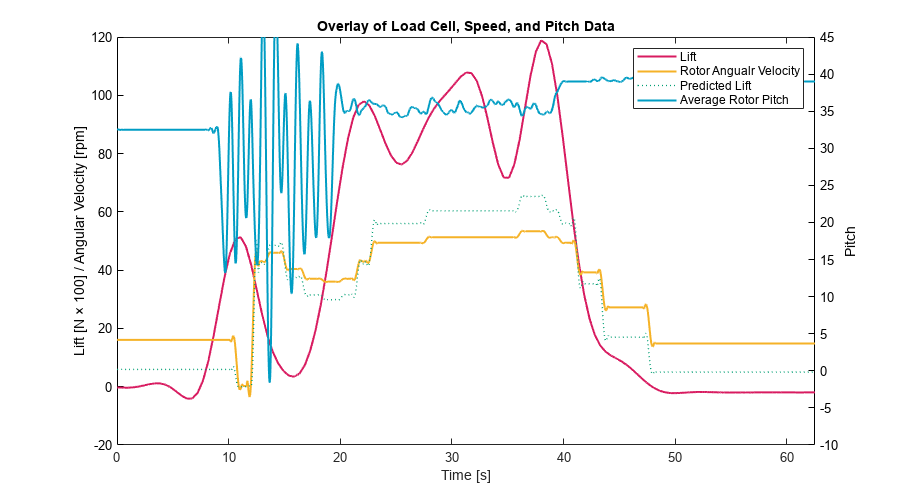

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 30.1.csv"

resultsForwardDirection = 6252×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 10:40:11         30             16.06             30               29                 37               -22            24             -35            24     
    2024-10-15 10:40:11         30             16.06             30               29                 36   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 30.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4809    0.9618    1.4428    1.9237    2.4046    2.8855    3.3665    3.8474    4.3283    4.8092    5.2902    5.7711    6.2520    6.7329    7.2138    7.6948    8.1757    8.6566    9.1375    9.6185   10.0994   10.5803   11.0612   11.5422   12.0231   12.5040   12.9849   13.4658   13.9468   14.4277   14.9086   15.3895   15.8705   16.3514   16.8323   17.3132   17.7942   18.2751   18.7560   19.2369   19.7178   20.1988   20.6797   21.1606   21.6415   22.1225   22.6034   23.0843   23.5652


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 30.2.csv"

resultsForwardDirection = 7858×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 10:42:32         30             0.91              27               76                 48               -46            49             -53            44     
    2024-10-15 10:42:32         30             0.91              27               76                 48   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 30.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4762    0.9525    1.4287    1.9050    2.3812    2.8575    3.3337    3.8099    4.2862    4.7624    5.2387    5.7149    6.1912    6.6674    7.1436    7.6199    8.0961    8.5724    9.0486    9.5248   10.0011   10.4773   10.9536   11.4298   11.9061   12.3823   12.8585   13.3348   13.8110   14.2873   14.7635   15.2398   15.7160   16.1922   16.6685   17.1447   17.6210   18.0972   18.5735   19.0497   19.5259   20.0022   20.4784   20.9547   21.4309   21.9072   22.3834   22.8596   23.3359


previousItterationPoint = 1

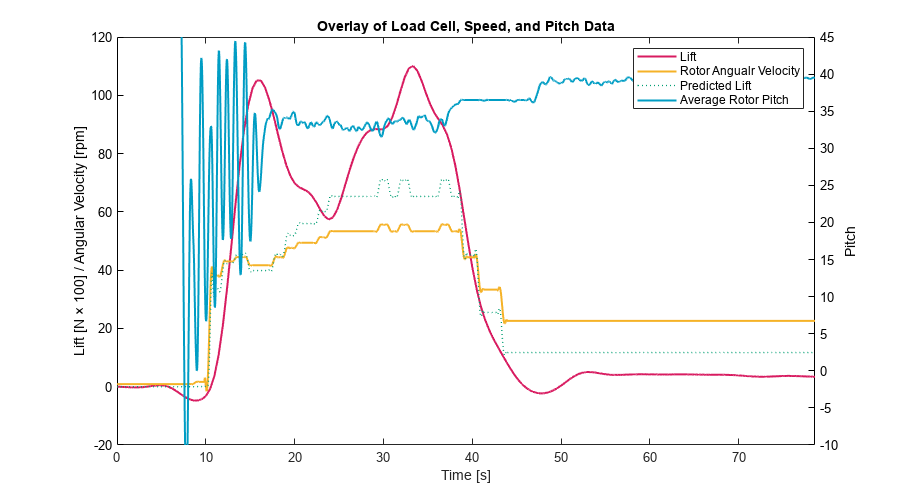

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 30.3.csv"

resultsForwardDirection = 7425×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 10:45:06         30              0.7              27               41                 38               -52            54             -55            34     
    2024-10-15 10:45:06         30              0.7              27               41                 38   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 30.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4790    0.9581    1.4371    1.9161    2.3952    2.8742    3.3532    3.8323    4.3113    4.7903    5.2694    5.7484    6.2274    6.7065    7.1855    7.6645    8.1435    8.6226    9.1016    9.5806   10.0597   10.5387   11.0177   11.4968   11.9758   12.4548   12.9339   13.4129   13.8919   14.3710   14.8500   15.3290   15.8081   16.2871   16.7661   17.2452   17.7242   18.2032   18.6823   19.1613   19.6403   20.1194   20.5984   21.0774   21.5565   22.0355   22.5145   22.9935   23.4726


previousItterationPoint = 1

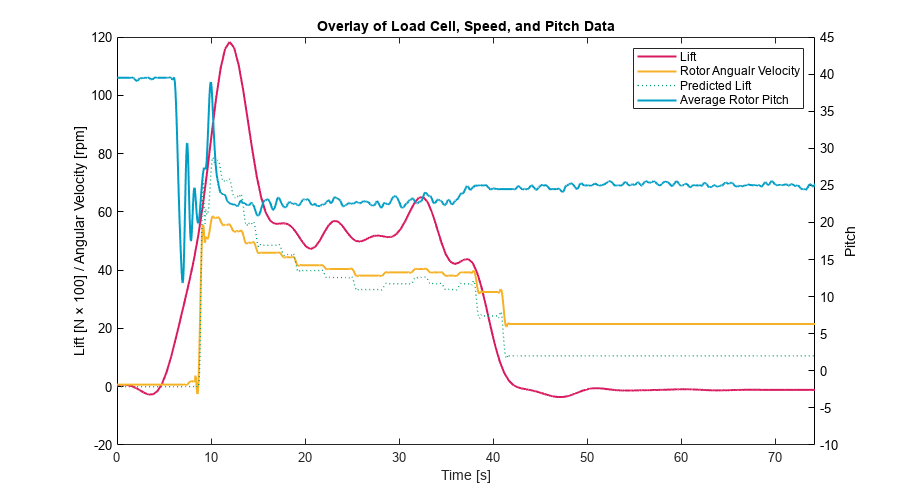

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 30.4.csv"

resultsForwardDirection = 5263×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 10:58:27         30             0.08              27               43                 37               -56            56             -57            43     
    2024-10-15 10:58:27         30             0.08              27               43                 37   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 30.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4785    0.9569    1.4354    1.9138    2.3923    2.8707    3.3492    3.8276    4.3061    4.7845    5.2630    5.7415    6.2199    6.6984    7.1768    7.6553    8.1337    8.6122    9.0906    9.5691   10.0475   10.5260   11.0045   11.4829   11.9614   12.4398   12.9183   13.3967   13.8752   14.3536   14.8321   15.3105   15.7890   16.2675   16.7459   17.2244   17.7028   18.1813   18.6597   19.1382   19.6166   20.0951   20.5735   21.0520   21.5305   22.0089   22.4874   22.9658   23.4443


previousItterationPoint = 1

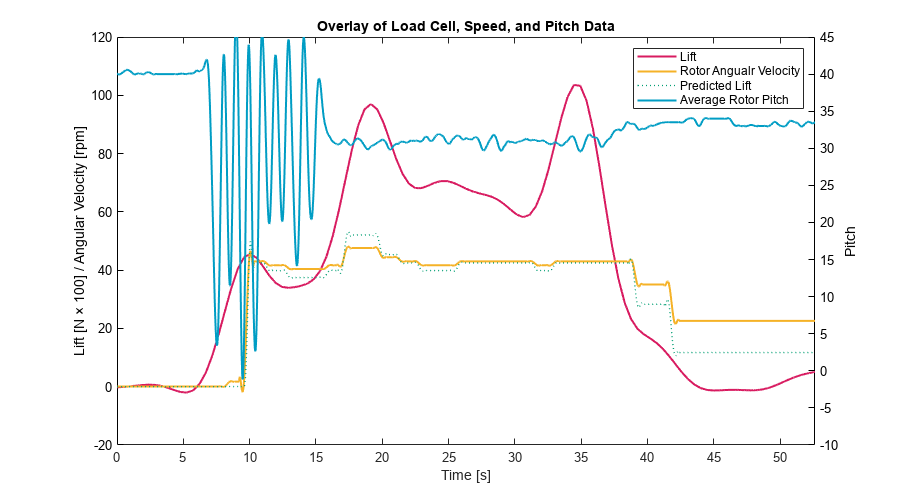

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 60.1.csv"

resultsForwardDirection = 6309×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:04:04         60             0.26              10               26                  8               -60             62            -61             45    
    2024-10-15 11:04:04         60             0.26              10               26                  8   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 60.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4744    0.9487    1.4231    1.8974    2.3718    2.8462    3.3205    3.7949    4.2692    4.7436    5.2180    5.6923    6.1667    6.6411    7.1154    7.5898    8.0641    8.5385    9.0129    9.4872    9.9616   10.4359   10.9103   11.3847   11.8590   12.3334   12.8077   13.2821   13.7565   14.2308   14.7052   15.1795   15.6539   16.1283   16.6026   17.0770   17.5514   18.0257   18.5001   18.9744   19.4488   19.9232   20.3975   20.8719   21.3462   21.8206   22.2950   22.7693   23.2437


previousItterationPoint = 1

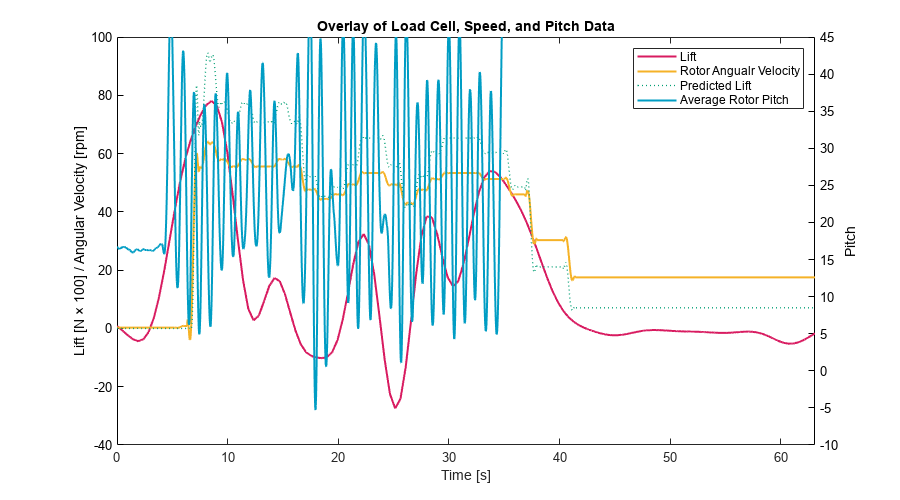

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 60.2.csv"

resultsForwardDirection = 10036×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:17:13         60             16.46             20               38                 37               -2              9             -8             11     
    2024-10-15 11:17:13         60             16.46             20               38                 37  

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 60.2.png"

TotalLoadcellScalled =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0008


ans =          0    0.4802    0.9604    1.4406    1.9208    2.4010    2.8811    3.3613    3.8415    4.3217    4.8019    5.2821    5.7623    6.2425    6.7227    7.2029    7.6831    8.1633    8.6434    9.1236    9.6038   10.0840   10.5642   11.0444   11.5246   12.0048   12.4850   12.9652   13.4454   13.9256   14.4057   14.8859   15.3661   15.8463   16.3265   16.8067   17.2869   17.7671   18.2473   18.7275   19.2077   19.6878   20.1680   20.6482   21.1284   21.6086   22.0888   22.5690   23.0492   23.5294


previousItterationPoint = 1

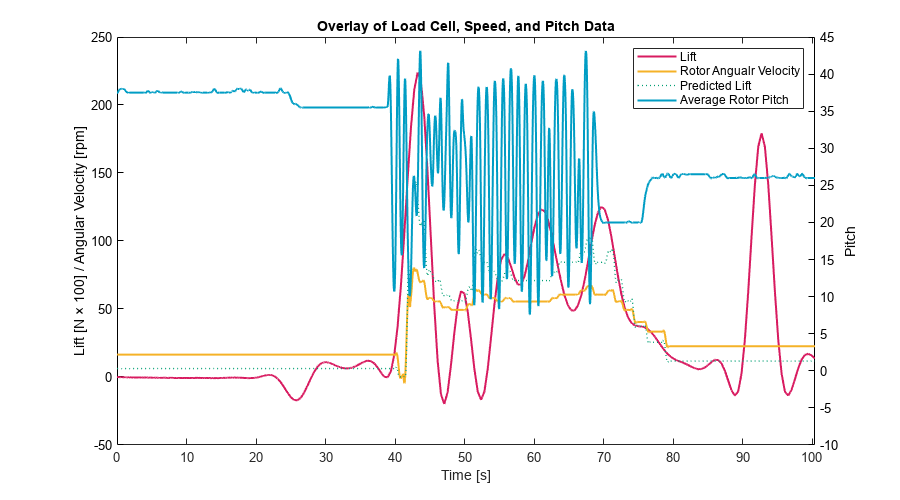

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 60.3.csv"

resultsForwardDirection = 5995×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:21:43         60             0.36              27               34                 29               -1              3              0             -1     
    2024-10-15 11:21:43         60             0.36              27               34                 29   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 60.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4758    0.9516    1.4274    1.9032    2.3790    2.8548    3.3306    3.8063    4.2821    4.7579    5.2337    5.7095    6.1853    6.6611    7.1369    7.6127    8.0885    8.5643    9.0401    9.5159    9.9917   10.4675   10.9433   11.4190   11.8948   12.3706   12.8464   13.3222   13.7980   14.2738   14.7496   15.2254   15.7012   16.1770   16.6528   17.1286   17.6044   18.0802   18.5560   19.0317   19.5075   19.9833   20.4591   20.9349   21.4107   21.8865   22.3623   22.8381   23.3139


previousItterationPoint = 1

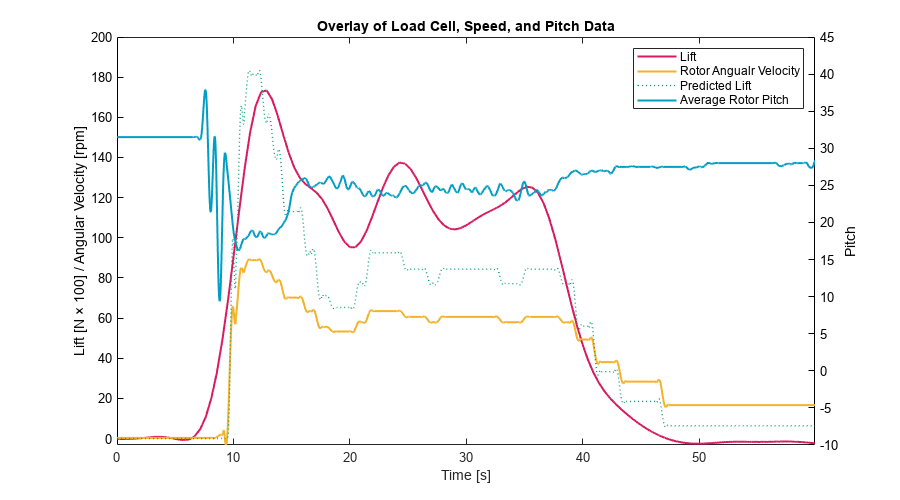

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 60.4.csv"

resultsForwardDirection = 7480×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:23:32         60             19.32             13               32                 46                 3            -1              -3            -1     
    2024-10-15 11:23:32         60             19.32             13               32                 46   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 60.4.png"

TotalLoadcellScalled =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0001    0.0010    0.0018    0.0027


ans =          0    0.4589    0.9178    1.3767    1.8356    2.2945    2.7534    3.2123    3.6712    4.1301    4.5890    5.0479    5.5067    5.9656    6.4245    6.8834    7.3423    7.8012    8.2601    8.7190    9.1779    9.6368   10.0957   10.5546   11.0135   11.4724   11.9313   12.3902   12.8491   13.3080   13.7669   14.2258   14.6847   15.1436   15.6025   16.0613   16.5202   16.9791   17.4380   17.8969   18.3558   18.8147   19.2736   19.7325   20.1914   20.6503   21.1092   21.5681   22.0270   22.4859


previousItterationPoint = 1

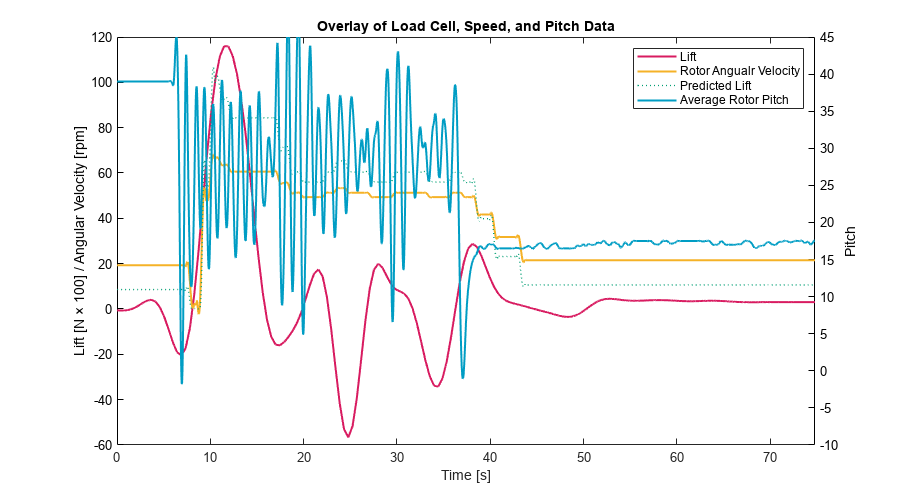

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 90.1.csv"

resultsForwardDirection = 9683×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:26:34         90             21.51             13               44                 55                4              4             -12            17     
    2024-10-15 11:26:34         90             21.51             13               44                 55   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 90.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4817    0.9635    1.4452    1.9270    2.4087    2.8904    3.3722    3.8539    4.3357    4.8174    5.2992    5.7809    6.2626    6.7444    7.2261    7.7079    8.1896    8.6713    9.1531    9.6348   10.1166   10.5983   11.0800   11.5618   12.0435   12.5253   13.0070   13.4888   13.9705   14.4522   14.9340   15.4157   15.8975   16.3792   16.8609   17.3427   17.8244   18.3062   18.7879   19.2697   19.7514   20.2331   20.7149   21.1966   21.6784   22.1601   22.6418   23.1236   23.6053


previousItterationPoint = 1

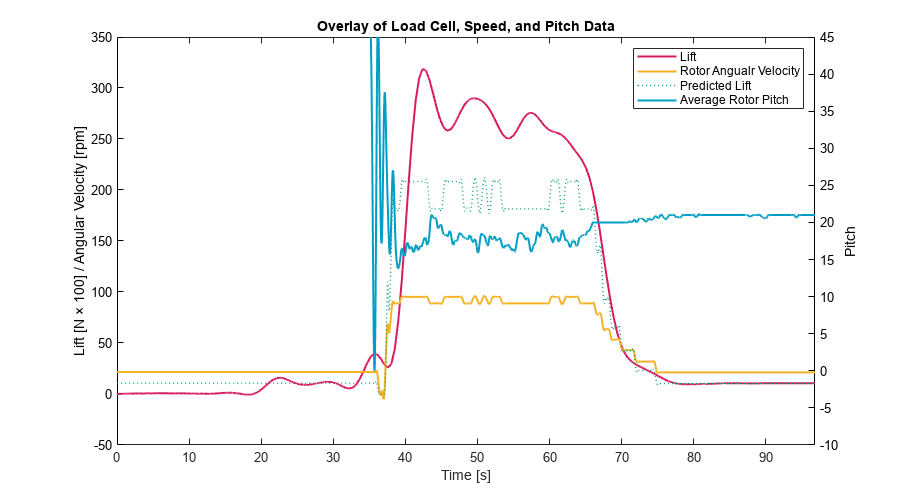

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 90.2.csv"

resultsForwardDirection = 6841×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:32:16         90             0.27              27               63                 59                10            -39             64            -56    
    2024-10-15 11:32:16         90             0.27              27               63                 59   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 90.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4784    0.9568    1.4352    1.9136    2.3920    2.8703    3.3487    3.8271    4.3055    4.7839    5.2623    5.7407    6.2191    6.6975    7.1759    7.6543    8.1327    8.6110    9.0894    9.5678   10.0462   10.5246   11.0030   11.4814   11.9598   12.4382   12.9166   13.3950   13.8734   14.3517   14.8301   15.3085   15.7869   16.2653   16.7437   17.2221   17.7005   18.1789   18.6573   19.1357   19.6141   20.0924   20.5708   21.0492   21.5276   22.0060   22.4844   22.9628   23.4412


previousItterationPoint = 1

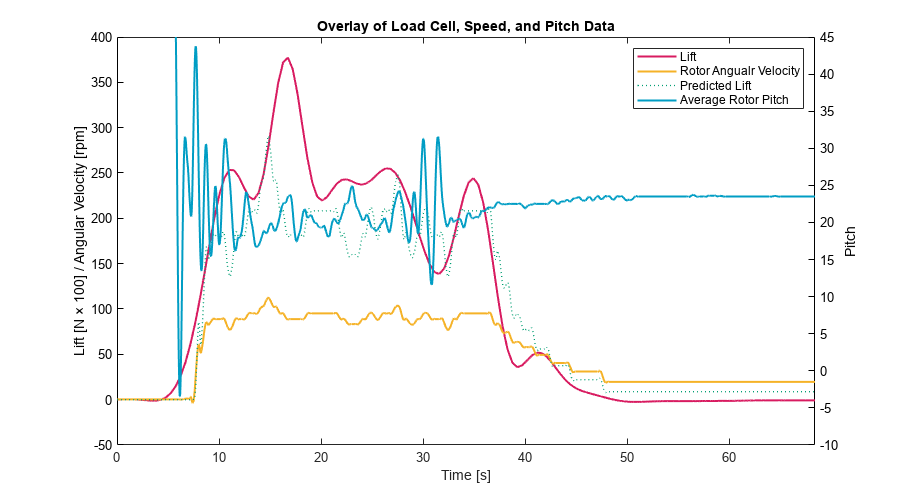

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 90.3.csv"

resultsForwardDirection = 6653×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:34:15         90             19.61             13               31                 23               20             -51            72             -61    
    2024-10-15 11:34:15         90             19.61             13               31                 23   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 90.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4786    0.9573    1.4359    1.9145    2.3932    2.8718    3.3504    3.8291    4.3077    4.7863    5.2650    5.7436    6.2222    6.7009    7.1795    7.6581    8.1368    8.6154    9.0940    9.5727   10.0513   10.5299   11.0086   11.4872   11.9658   12.4445   12.9231   13.4017   13.8804   14.3590   14.8376   15.3163   15.7949   16.2735   16.7522   17.2308   17.7094   18.1881   18.6667   19.1453   19.6240   20.1026   20.5812   21.0599   21.5385   22.0171   22.4958   22.9744   23.4530


previousItterationPoint = 1

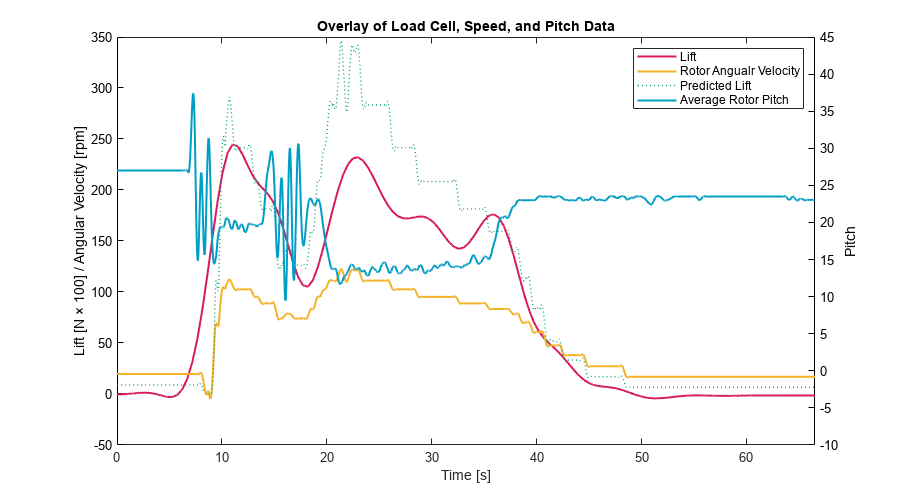

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 90.4.csv"

resultsForwardDirection = 7854×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:36:11         90             1.36              30               23                 23               22             -52            72             -64    
    2024-10-15 11:36:11         90             1.36              30               23                 23   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 90.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4789    0.9578    1.4367    1.9156    2.3945    2.8734    3.3523    3.8312    4.3101    4.7890    5.2679    5.7468    6.2257    6.7046    7.1835    7.6624    8.1413    8.6202    9.0991    9.5780   10.0570   10.5359   11.0148   11.4937   11.9726   12.4515   12.9304   13.4093   13.8882   14.3671   14.8460   15.3249   15.8038   16.2827   16.7616   17.2405   17.7194   18.1983   18.6772   19.1561   19.6350   20.1139   20.5928   21.0717   21.5506   22.0295   22.5084   22.9873   23.4662


previousItterationPoint = 1

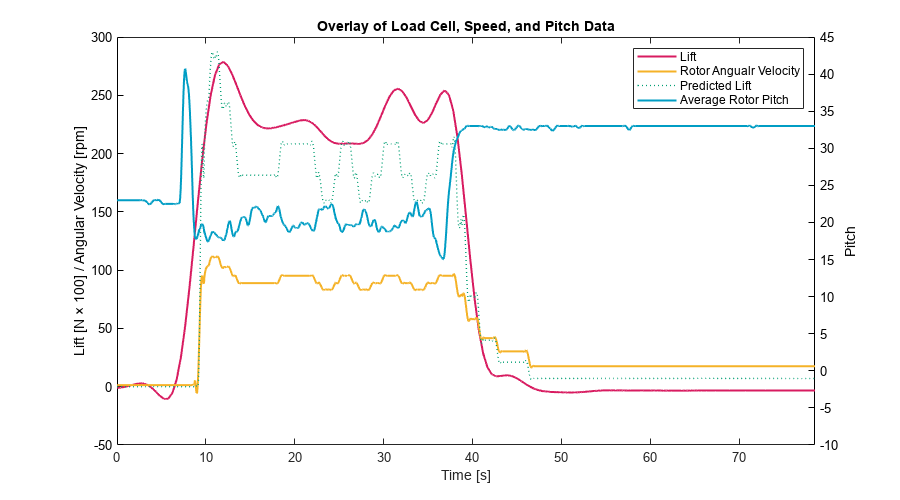

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 120.1.csv"

resultsForwardDirection = 8435×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:38:23        120             17.54             13               42                 23               27             -59            81             -71    
    2024-10-15 11:38:23        120             17.54             13               42                 23   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 120.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4820    0.9640    1.4460    1.9280    2.4100    2.8920    3.3740    3.8560    4.3380    4.8200    5.3020    5.7840    6.2660    6.7480    7.2300    7.7120    8.1940    8.6760    9.1580    9.6400   10.1220   10.6040   11.0860   11.5680   12.0500   12.5320   13.0140   13.4960   13.9780   14.4600   14.9420   15.4240   15.9060   16.3880   16.8700   17.3520   17.8340   18.3160   18.7980   19.2800   19.7620   20.2440   20.7260   21.2080   21.6900   22.1720   22.6540   23.1360   23.6180


previousItterationPoint = 1

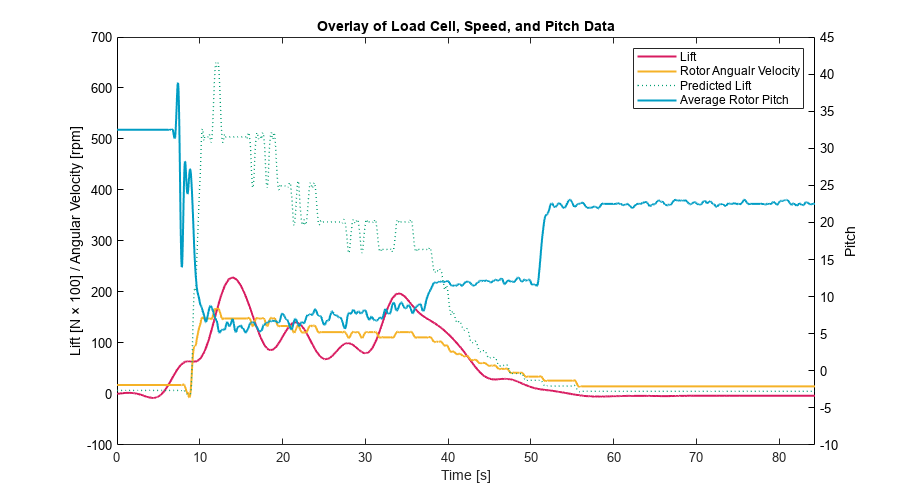

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 120.2.csv"

resultsForwardDirection = 5371×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:40:30        120             14.98             27               33                 18                16            -46             68            -58    
    2024-10-15 11:40:30        120             14.98             27               33                 18   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 120.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4839    0.9677    1.4516    1.9355    2.4194    2.9032    3.3871    3.8710    4.3549    4.8387    5.3226    5.8065    6.2904    6.7742    7.2581    7.7420    8.2259    8.7097    9.1936    9.6775   10.1614   10.6452   11.1291   11.6130   12.0968   12.5807   13.0646   13.5485   14.0323   14.5162   15.0001   15.4840   15.9678   16.4517   16.9356   17.4195   17.9033   18.3872   18.8711   19.3550   19.8388   20.3227   20.8066   21.2905   21.7743   22.2582   22.7421   23.2259   23.7098


previousItterationPoint = 1

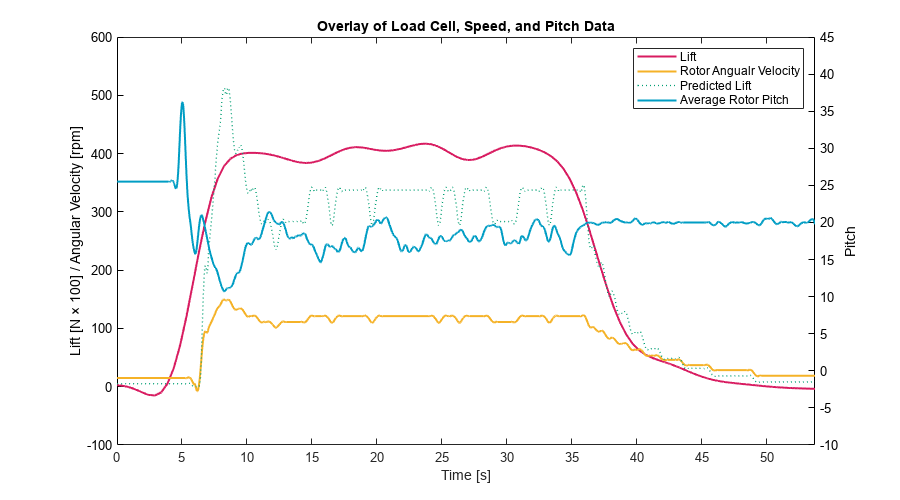

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 120.3.csv"

resultsForwardDirection = 6239×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:43:52        120              0.6              30               32                 24                16            -45             61            -53    
    2024-10-15 11:43:52        120              0.6              30               32                 24   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 120.3.png"

TotalLoadcellScalled =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0005


ans =          0    0.4836    0.9673    1.4509    1.9346    2.4182    2.9019    3.3855    3.8691    4.3528    4.8364    5.3201    5.8037    6.2874    6.7710    7.2547    7.7383    8.2219    8.7056    9.1892    9.6729   10.1565   10.6402   11.1238   11.6074   12.0911   12.5747   13.0584   13.5420   14.0257   14.5093   14.9929   15.4766   15.9602   16.4439   16.9275   17.4112   17.8948   18.3784   18.8621   19.3457   19.8294   20.3130   20.7967   21.2803   21.7640   22.2476   22.7312   23.2149   23.6985


previousItterationPoint = 1

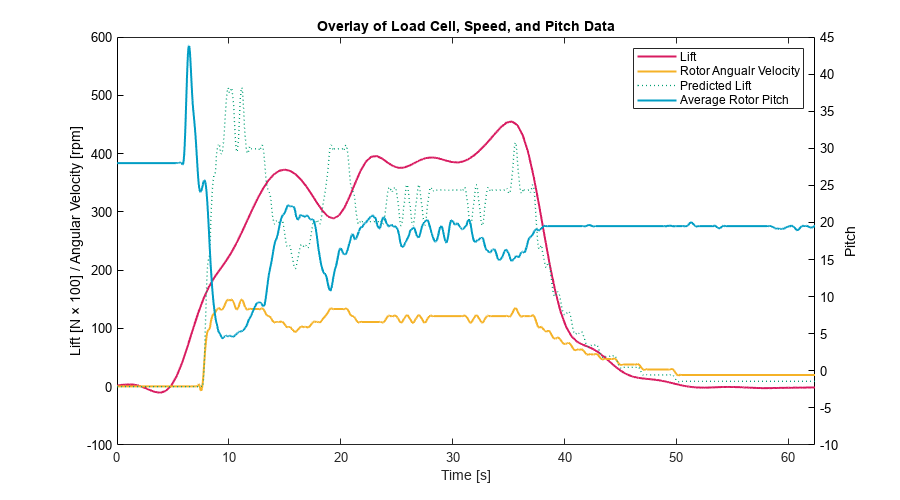

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 120.4.csv"

resultsForwardDirection = 6189×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:48:24        120             0.33              27               74                 49                5             -10              4             -1    
    2024-10-15 11:48:24        120             0.33              27               74                 49   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 120.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4835    0.9670    1.4505    1.9341    2.4176    2.9011    3.3846    3.8681    4.3516    4.8352    5.3187    5.8022    6.2857    6.7692    7.2527    7.7363    8.2198    8.7033    9.1868    9.6703   10.1538   10.6373   11.1209   11.6044   12.0879   12.5714   13.0549   13.5384   14.0220   14.5055   14.9890   15.4725   15.9560   16.4395   16.9230   17.4066   17.8901   18.3736   18.8571   19.3406   19.8241   20.3077   20.7912   21.2747   21.7582   22.2417   22.7252   23.2088   23.6923


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 150.1.csv"

resultsForwardDirection = 5970×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:51:10        150             17.09             13               31                 17               -6               3            -10             16    
    2024-10-15 11:51:10        150             17.09             13               31                 17   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 150.1.png"

TotalLoadcellScalled = 1×5970
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×124
         0    0.4854    0.9707    1.4561    1.9415    2.4268    2.9122    3.3976    3.8829    4.3683    4.8537    5.3390    5.8244    6.3098    6.7951    7.2805    7.7659    8.2512    8.7366    9.2220    9.7073   10.1927   10.6780   11.1634   11.6488   12.1341   12.6195   13.1049   13.5902   14.0756


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 150.2.csv"

resultsForwardDirection = 10358×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:54:59        150             10.58             20               52                 46                0              0              0              1     
    2024-10-15 11:54:59        150             10.58             20               52                 46  

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 150.2.png"

TotalLoadcellScalled = 1×10358
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×215
         0    0.4840    0.9680    1.4521    1.9361    2.4201    2.9041    3.3881    3.8721    4.3562    4.8402    5.3242    5.8082    6.2922    6.7763    7.2603    7.7443    8.2283    8.7123    9.1964    9.6804   10.1644   10.6484   11.1324   11.6164   12.1005   12.5845   13.0685   13.5525   14.0365


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 150.3.csv"

resultsForwardDirection = 7382×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 12:00:04        150             0.59              13               55                 43                6             -13            18             -21    
    2024-10-15 12:00:04        150             0.59              13               55                 43   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 150.3.png"

TotalLoadcellScalled = 1×7382
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×153
         0    0.4857    0.9713    1.4570    1.9426    2.4283    2.9139    3.3996    3.8853    4.3709    4.8566    5.3422    5.8279    6.3136    6.7992    7.2849    7.7705    8.2562    8.7418    9.2275    9.7132   10.1988   10.6845   11.1701   11.6558   12.1414   12.6271   13.1128   13.5984   14.0841


previousItterationPoint = 1

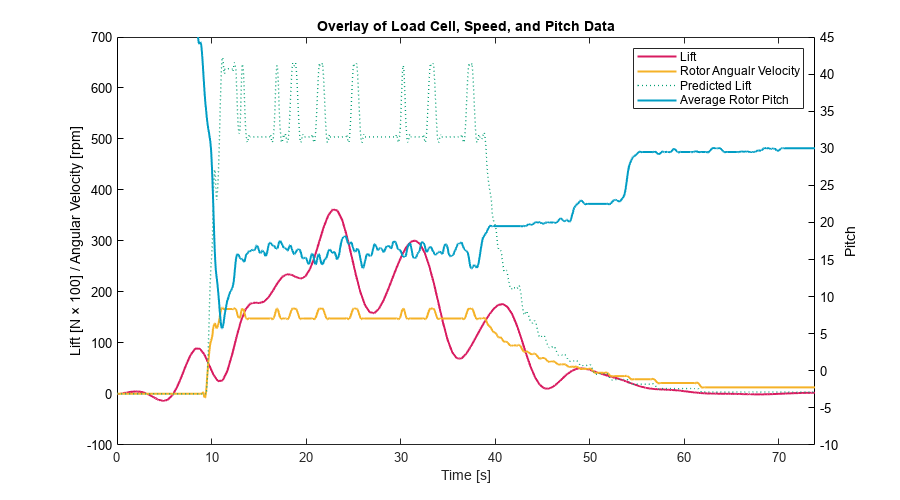

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\Test 150.4.csv"

resultsForwardDirection = 6156×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 12:07:09        150             0.18              27               56                 20               -7              1              9             -12    
    2024-10-15 12:07:09        150             0.18              27               56                 20   

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Forward Direction Graphs\Pitch Graph-Test 150.4.png"

TotalLoadcellScalled = 1×6156
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×129
         0    0.4809    0.9619    1.4428    1.9238    2.4047    2.8856    3.3666    3.8475    4.3284    4.8094    5.2903    5.7713    6.2522    6.7331    7.2141    7.6950    8.1759    8.6569    9.1378    9.6188   10.0997   10.5806   11.0616   11.5425   12.0234   12.5044   12.9853   13.4663   13.9472


previousItterationPoint = 1

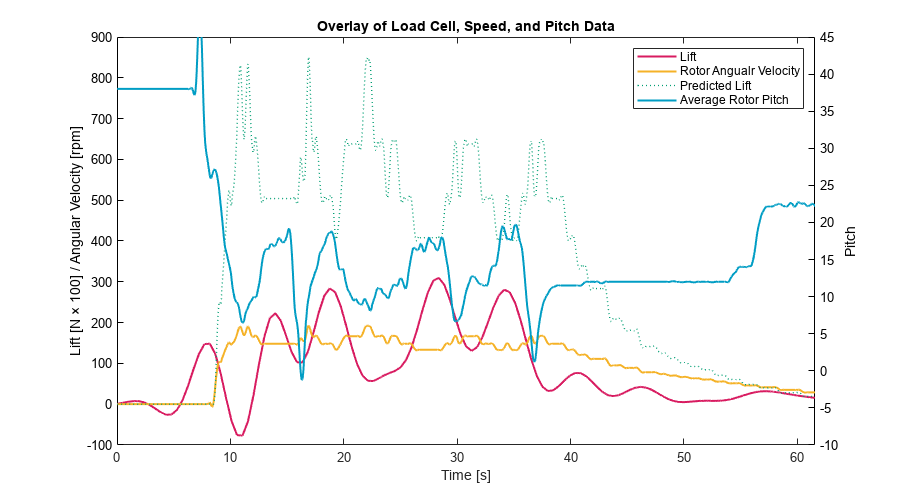

    predictedThrustFunction = @(x) 0.01805 .* (x .* pi/30).^2 + 0.002216 .* (x .* pi/30).^2/0.2625 .*sind(20);
    predictedThrust = predictedThrustFunction(sgolayfilt(resultsForwardDirection.("Current Speed"), 4, 111));
    
    clear alpha
    yyaxis left
    plot((1:length(aveargaePitch)).*10e-3, interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')*100,'color',"#D81B60", 'DisplayName', 'Lift', 'LineWidth', 1.5);
    hold on;
    plot((1:length(aveargaePitch)).*10e-3, sgolayfilt(resultsForwardDirection.("Current Speed"), 4, 111),'Linestyle','-', 'color',"#f5b227",'DisplayName', 'Rotor Angualr Velocity', 'LineWidth', 1.5);
    plot((1:length(aveargaePitch)).*10e-3,predictedThrust*100,'Linestyle',':','color',"#009E73", 'DisplayName', 'Predicted Lift', 'LineWidth', 1)
    alpha(0); % Set transparency for better visibility
    ylabel('Lift [N × 100] / Angular Velocity [rpm]');
    ax = gca;
    ax.YColor = 'k'; % Set color to black for consistency
    
    yyaxis right
    plot((1:length(aveargaePitch))*10e-3, sgolayfilt(aveargaePitch, 4, 111),'color',"#009DC4", 'DisplayName', 'Average Rotor Pitch', 'LineWidth', 1.5);
    alpha(0.2); % Set transparency
    ylabel('Pitch');
    ax.YColor = 'k'; % Set color to black for consistency
    ylim([-10,45])
        
    xlabel('Time [s]');
    title('Overlay of Load Cell, Speed, and Pitch Data');
    legend;
    xlim([0,length(resultsForwardDirection.Timestamp)*10e-3])
    % grid on;
    hold off;

    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Lift, Pitch and Speed-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

end